# FNN CNN LSTM - Self Veriloadfy

clear

# 저장된 데이타를 모두 읽어들인다.

load ryan_gen_data

# Load model 

load ryan_gen_data_model

# Prediciton #05 by model #05 - Full Data

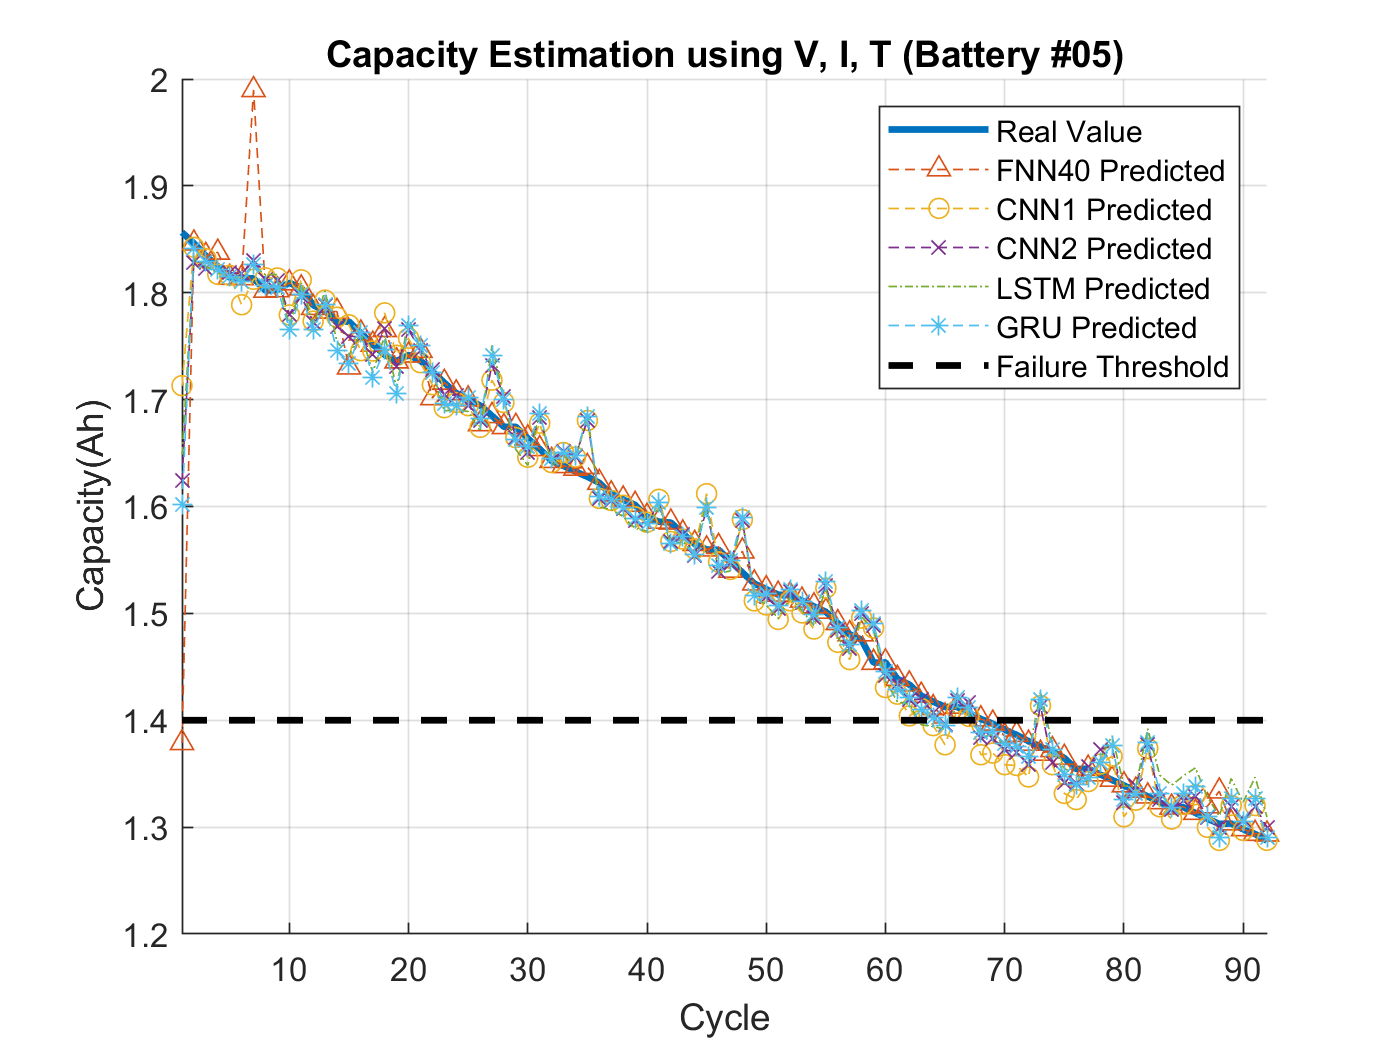


BatteryNumString = '05';
ModelNumString = '05' ;

pFNN40_05 = netFNN40_05_v2(x_05');
total_cycle = length(pFNN40_05);
cellx = num2cell(x_05', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_05 = predict(netCNN1_05_v2, x_4d);
pCNN2_05 = predict(netCNN2_05_v2, x_4d);
pLSTM_05 = cell2mat(predict(netLSTM_05_v2, num2cell(x_05', 1)));
pGRU_05 = cell2mat(predict(netGRU_05_v2, num2cell(x_05', 1)));

y_05 = yCap_05*cap_all_rate + cap_all_min;
pFNN40_05 = pFNN40_05*cap_all_rate + cap_all_min;
pCNN1_05 = pCNN1_05*cap_all_rate + cap_all_min;
pCNN2_05 = pCNN2_05*cap_all_rate + cap_all_min;
pLSTM_05 = pLSTM_05*cap_all_rate + cap_all_min;
pGRU_05 = pGRU_05*cap_all_rate + cap_all_min;

figure, hold on, grid on,
plot(y_05, 'linewidth', 2), plot(pFNN40_05, '^--'), plot(pCNN1_05, 'o--'), plot(pCNN2_05, 'x--'), plot(pLSTM_05, '-.'),plot(pGRU_05, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_05 = sqrt(mean(( y_05 - pFNN40_05' ).^2))

rmse_pFNN40_05 = 0.0537

rmse_pCNN1_05  = sqrt(mean(( y_05 - pCNN1_05 ).^2))

rmse_pCNN1_05 = single
0.0256

rmse_pCNN2_05  = sqrt(mean(( y_05 - pCNN2_05 ).^2))

rmse_pCNN2_05 = single
0.0303

rmse_pLSTM_05  = sqrt(mean(( y_05 - pLSTM_05 ).^2))

rmse_pLSTM_05 = single
0.0326

rmse_pGRU_05   = sqrt(mean(( y_05 - pGRU_05  ).^2))

rmse_pGRU_05 = single
0.0333


rmse_pFNN40_05

rmse_pFNN40_05 = 0.0537

rmse_pCNN1_05 

rmse_pCNN1_05 = single
0.0256

rmse_pCNN2_05 

rmse_pCNN2_05 = single
0.0303

rmse_pLSTM_05 

rmse_pLSTM_05 = single
0.0326

rmse_pGRU_05  

rmse_pGRU_05 = single
0.0333

# Prediciton #06 by model #06 - Full Data

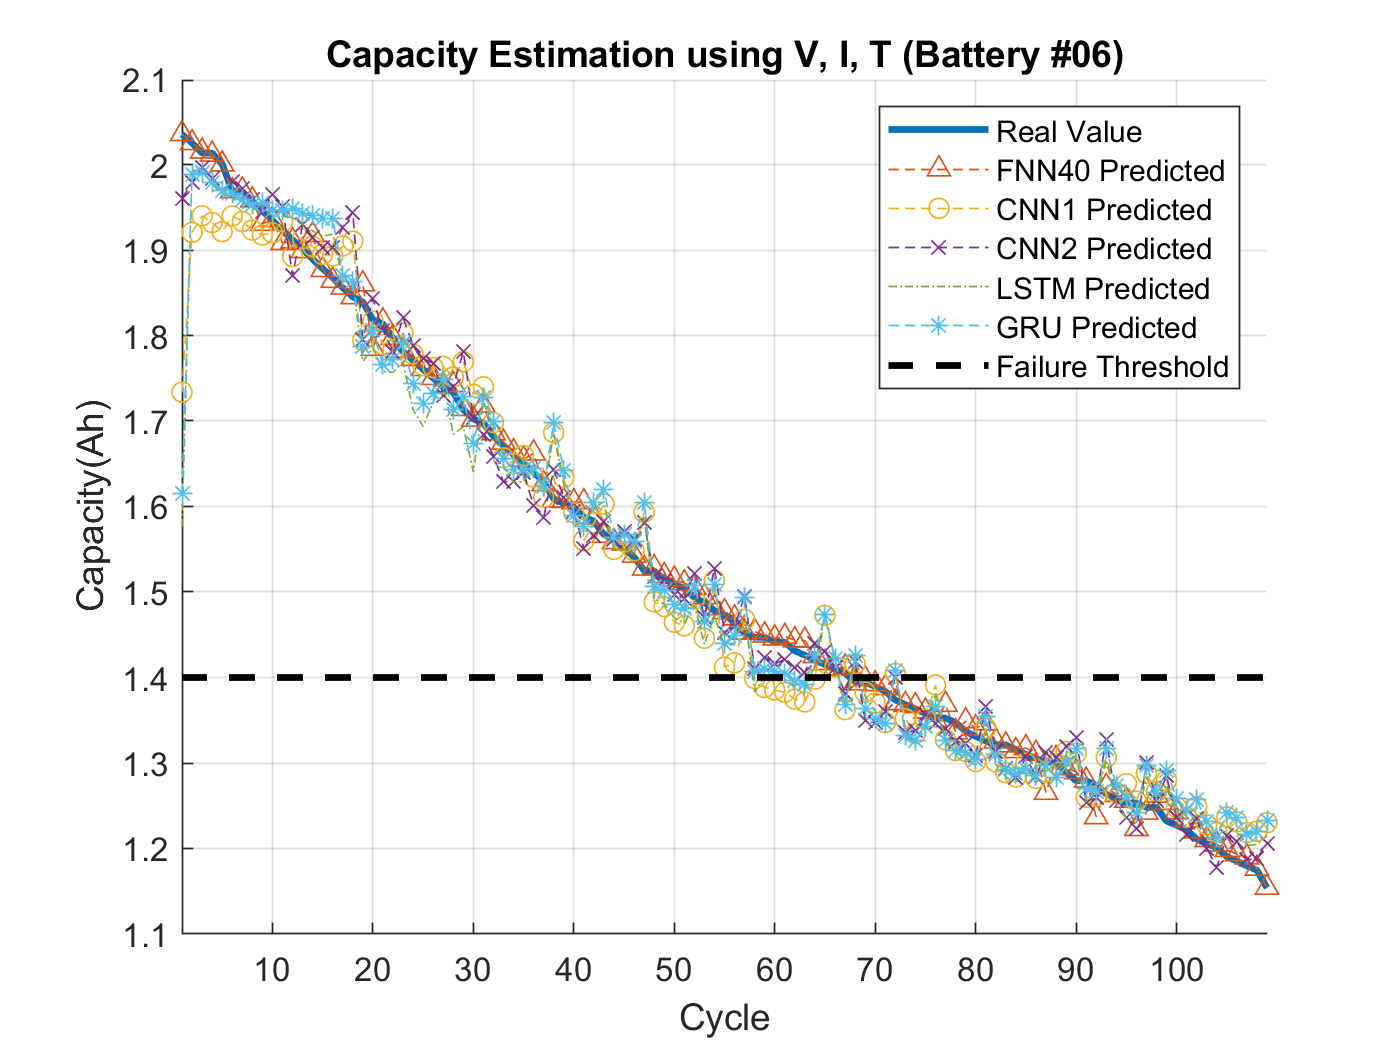


BatteryNumString = '06';
ModelNumString = '06' ;

pFNN40_06 = netFNN40_06_v2(x_06');
total_cycle = length(pFNN40_06);
cellx = num2cell(x_06', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_06 = predict(netCNN1_06_v2, x_4d);
pCNN2_06 = predict(netCNN2_06_v2, x_4d);
pLSTM_06 = cell2mat(predict(netLSTM_06_v2, num2cell(x_06', 1)));
pGRU_06 = cell2mat(predict(netGRU_06_v2, num2cell(x_06', 1)));

y_06 = yCap_06*cap_all_rate + cap_all_min;
pFNN40_06 = pFNN40_06*cap_all_rate + cap_all_min;
pCNN1_06 = pCNN1_06*cap_all_rate + cap_all_min;
pCNN2_06 = pCNN2_06*cap_all_rate + cap_all_min;
pLSTM_06 = pLSTM_06*cap_all_rate + cap_all_min;
pGRU_06 = pGRU_06*cap_all_rate + cap_all_min;

figure, hold on, grid on,
plot(y_06, 'linewidth', 2), plot(pFNN40_06, '^--'), plot(pCNN1_06, 'o--'), plot(pCNN2_06, 'x--'), plot(pLSTM_06, '-.'),plot(pGRU_06, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_06 = sqrt(mean(( y_06 - pFNN40_06' ).^2))

rmse_pFNN40_06 = 0.0104

rmse_pCNN1_06  = sqrt(mean(( y_06 - pCNN1_06 ).^2))

rmse_pCNN1_06 = single
0.0465

rmse_pCNN2_06  = sqrt(mean(( y_06 - pCNN2_06 ).^2))

rmse_pCNN2_06 = single
0.0303

rmse_pLSTM_06  = sqrt(mean(( y_06 - pLSTM_06 ).^2))

rmse_pLSTM_06 = single
0.0547

rmse_pGRU_06   = sqrt(mean(( y_06 - pGRU_06  ).^2))

rmse_pGRU_06 = single
0.0519


rmse_pFNN40_06

rmse_pFNN40_06 = 0.0104

rmse_pCNN1_06 

rmse_pCNN1_06 = single
0.0465

rmse_pCNN2_06 

rmse_pCNN2_06 = single
0.0303

rmse_pLSTM_06 

rmse_pLSTM_06 = single
0.0547

rmse_pGRU_06  

rmse_pGRU_06 = single
0.0519

# Prediciton #07 by model #07 - Full Data

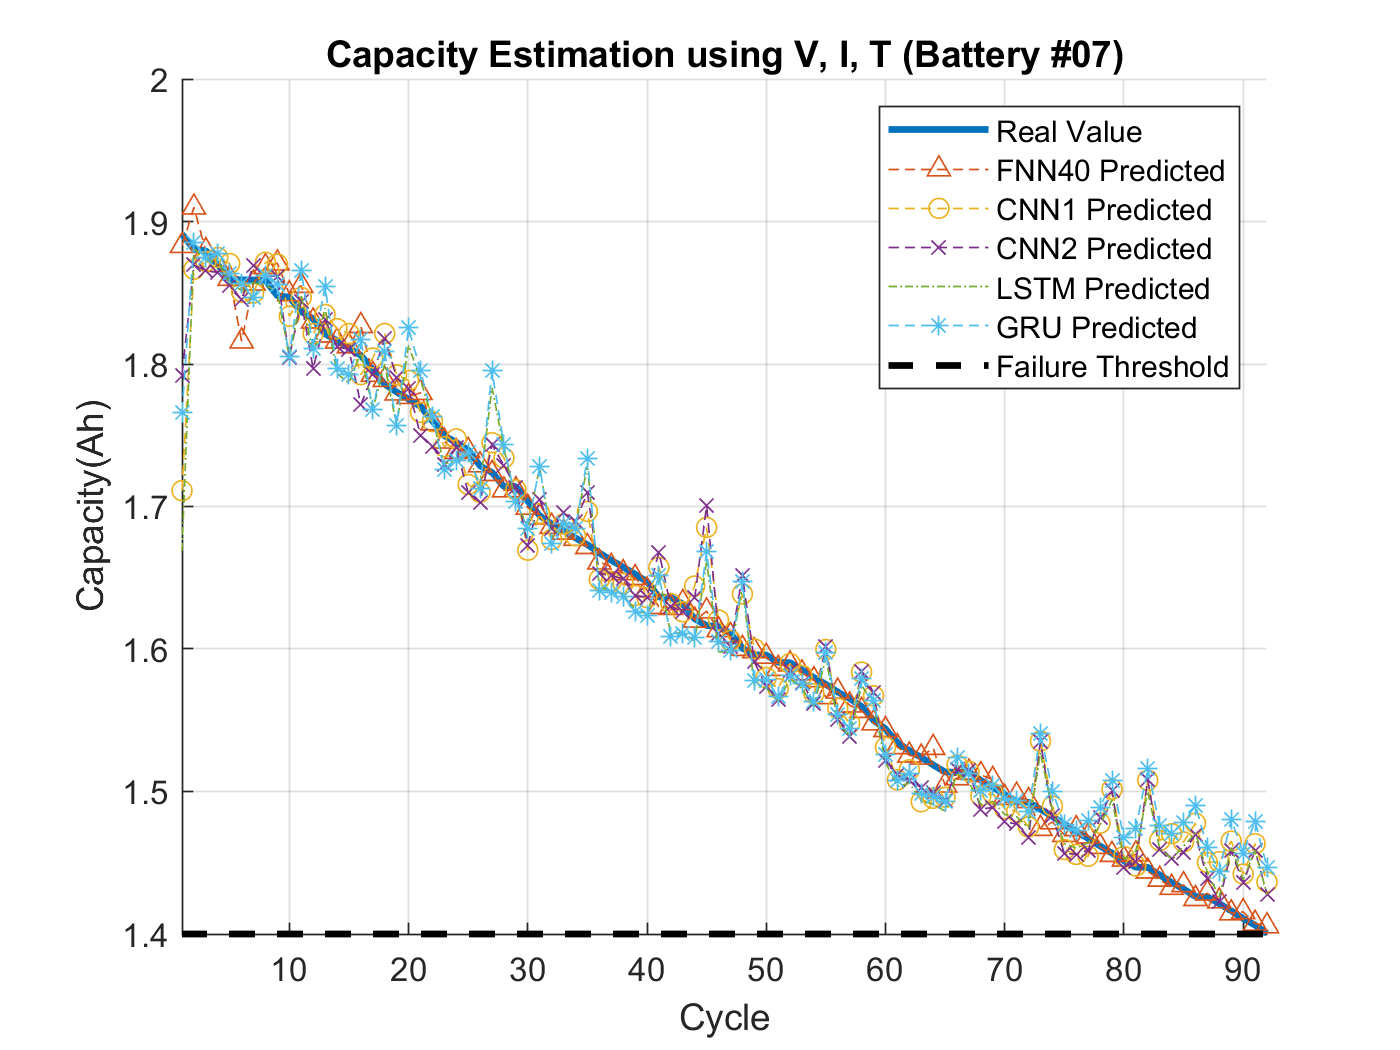


BatteryNumString = '07';
ModelNumString = '07' ;

pFNN40_07 = netFNN40_07_v2(x_07');
total_cycle = length(pFNN40_07);
cellx = num2cell(x_07', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_07 = predict(netCNN1_07_v2, x_4d);
pCNN2_07 = predict(netCNN2_07_v2, x_4d);
pLSTM_07 = cell2mat(predict(netLSTM_07_v2, num2cell(x_07', 1)));
pGRU_07 = cell2mat(predict(netGRU_07_v2, num2cell(x_07', 1)));

y_07 = yCap_07*cap_all_rate + cap_all_min;
pFNN40_07 = pFNN40_07*cap_all_rate + cap_all_min;
pCNN1_07 = pCNN1_07*cap_all_rate + cap_all_min;
pCNN2_07 = pCNN2_07*cap_all_rate + cap_all_min;
pLSTM_07 = pLSTM_07*cap_all_rate + cap_all_min;
pGRU_07 = pGRU_07*cap_all_rate + cap_all_min;

figure, hold on, grid on,
plot(y_07, 'linewidth', 2), plot(pFNN40_07, '^--'), plot(pCNN1_07, 'o--'), plot(pCNN2_07, 'x--'), plot(pLSTM_07, '-.'),plot(pGRU_07, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_07 = sqrt(mean(( y_07 - pFNN40_07' ).^2))

rmse_pFNN40_07 = 0.0078

rmse_pCNN1_07  = sqrt(mean(( y_07 - pCNN1_07 ).^2))

rmse_pCNN1_07 = single
0.0292

rmse_pCNN2_07  = sqrt(mean(( y_07 - pCNN2_07 ).^2))

rmse_pCNN2_07 = single
0.0258

rmse_pLSTM_07  = sqrt(mean(( y_07 - pLSTM_07 ).^2))

rmse_pLSTM_07 = single
0.0332

rmse_pGRU_07   = sqrt(mean(( y_07 - pGRU_07  ).^2))

rmse_pGRU_07 = single
0.0315


rmse_pFNN40_07

rmse_pFNN40_07 = 0.0078

rmse_pCNN1_07 

rmse_pCNN1_07 = single
0.0292

rmse_pCNN2_07 

rmse_pCNN2_07 = single
0.0258

rmse_pLSTM_07 

rmse_pLSTM_07 = single
0.0332

rmse_pGRU_07  

rmse_pGRU_07 = single
0.0315

# Prediciton #0506 by model #0506 - Full Data

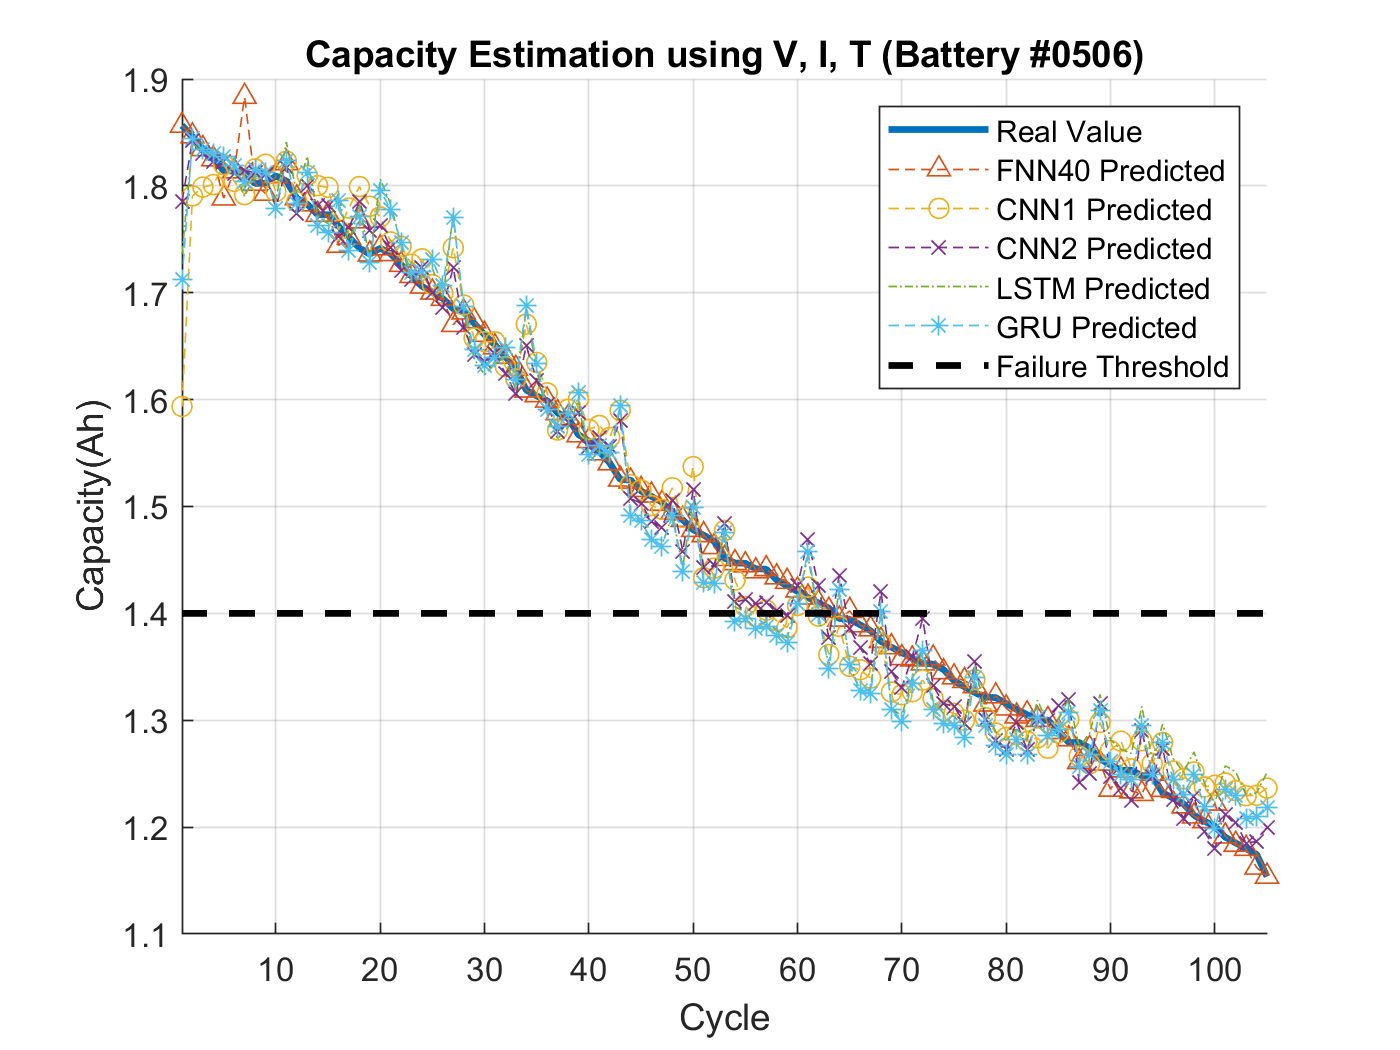


BatteryNumString = '0506';
ModelNumString = '0506' ;

pFNN40_0506 = netFNN40_0506_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_0506_v2, x_4d);
pCNN2_0506 = predict(netCNN2_0506_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_0506_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_0506_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506*cap_all_rate + cap_all_min;
pFNN40_0506 = pFNN40_0506*cap_all_rate + cap_all_min;
pCNN1_0506 = pCNN1_0506*cap_all_rate + cap_all_min;
pCNN2_0506 = pCNN2_0506*cap_all_rate + cap_all_min;
pLSTM_0506 = pLSTM_0506*cap_all_rate + cap_all_min;
pGRU_0506 = pGRU_0506*cap_all_rate + cap_all_min;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506 - pFNN40_0506' ).^2))

rmse_pFNN40_0506 = 0.0096

rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))

rmse_pCNN1_0506 = single
0.0400

rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))

rmse_pCNN2_0506 = single
0.0260

rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))

rmse_pLSTM_0506 = single
0.0389

rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))

rmse_pGRU_0506 = single
0.0371


rmse_pFNN40_0506

rmse_pFNN40_0506 = 0.0096

rmse_pCNN1_0506 

rmse_pCNN1_0506 = single
0.0400

rmse_pCNN2_0506 

rmse_pCNN2_0506 = single
0.0260

rmse_pLSTM_0506 

rmse_pLSTM_0506 = single
0.0389

rmse_pGRU_0506  

rmse_pGRU_0506 = single
0.0371

# Prediciton #0605 by model #0605 - Full Data

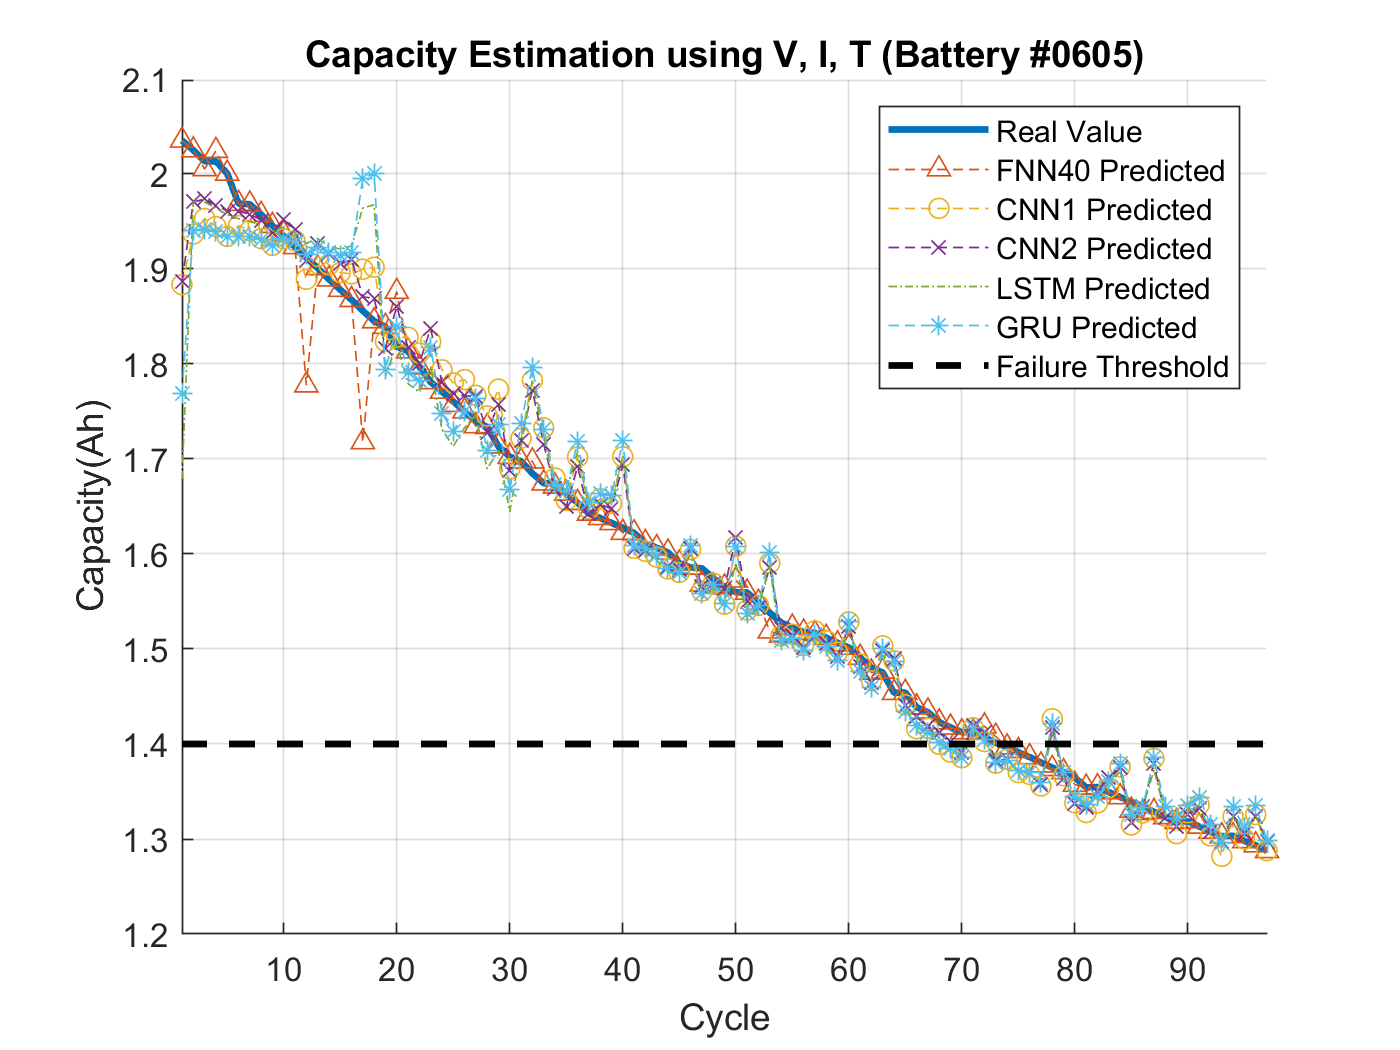


BatteryNumString = '0605';
ModelNumString = '0605' ;

pFNN40_0605 = netFNN40_0605_v2(x_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(x_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_0605_v2, x_4d);
pCNN2_0605 = predict(netCNN2_0605_v2, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_0605_v2, num2cell(x_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_0605_v2, num2cell(x_0605', 1)));

y_0605 = yCap_0605*cap_all_rate + cap_all_min;
pFNN40_0605 = pFNN40_0605*cap_all_rate + cap_all_min;
pCNN1_0605 = pCNN1_0605*cap_all_rate + cap_all_min;
pCNN2_0605 = pCNN2_0605*cap_all_rate + cap_all_min;
pLSTM_0605 = pLSTM_0605*cap_all_rate + cap_all_min;
pGRU_0605 = pGRU_0605*cap_all_rate + cap_all_min;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605 - pFNN40_0605' ).^2))

rmse_pFNN40_0605 = 0.0209

rmse_pCNN1_0605  = sqrt(mean(( y_0605 - pCNN1_0605 ).^2))

rmse_pCNN1_0605 = single
0.0341

rmse_pCNN2_0605  = sqrt(mean(( y_0605 - pCNN2_0605 ).^2))

rmse_pCNN2_0605 = single
0.0294

rmse_pLSTM_0605  = sqrt(mean(( y_0605 - pLSTM_0605 ).^2))

rmse_pLSTM_0605 = single
0.0486

rmse_pGRU_0605   = sqrt(mean(( y_0605 - pGRU_0605  ).^2))

rmse_pGRU_0605 = single
0.0472


rmse_pFNN40_0605

rmse_pFNN40_0605 = 0.0209

rmse_pCNN1_0605 

rmse_pCNN1_0605 = single
0.0341

rmse_pCNN2_0605 

rmse_pCNN2_0605 = single
0.0294

rmse_pLSTM_0605 

rmse_pLSTM_0605 = single
0.0486

rmse_pGRU_0605  

rmse_pGRU_0605 = single
0.0472

# Prediciton #05plus06 by model #05plus06 - Full Data

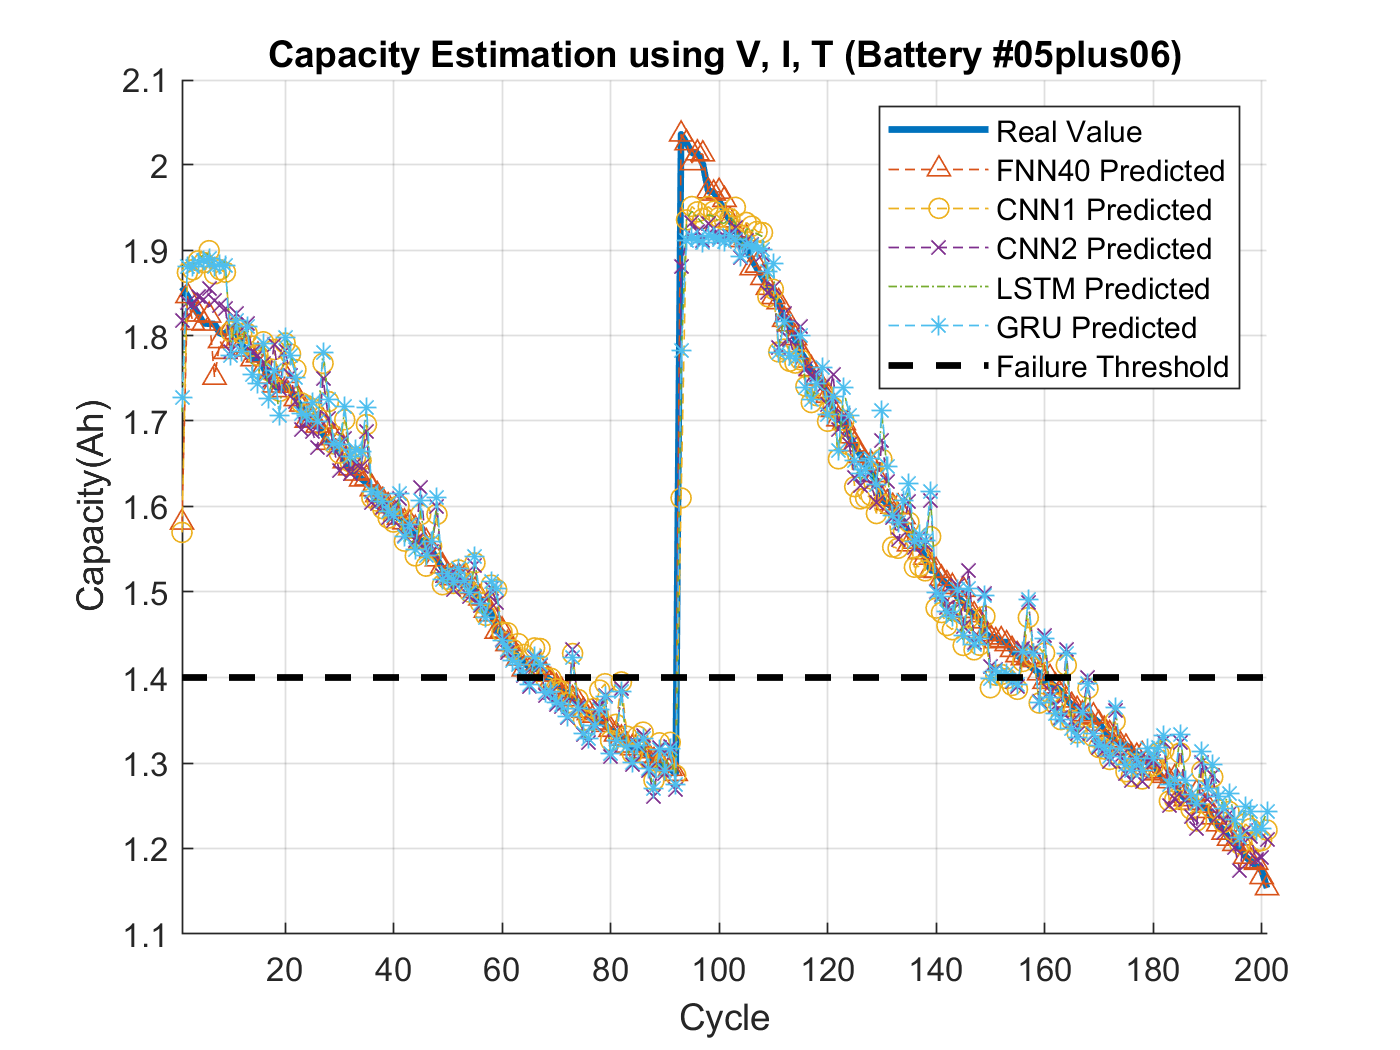


BatteryNumString = '05plus06';
ModelNumString = '05plus06' ;

pFNN40_05plus06 = netFNN40_05plus06_v2(x_05plus06');
total_cycle = length(pFNN40_05plus06);
cellx = num2cell(x_05plus06', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_05plus06 = predict(netCNN1_05plus06_v2, x_4d);
pCNN2_05plus06 = predict(netCNN2_05plus06_v2, x_4d);
pLSTM_05plus06 = cell2mat(predict(netLSTM_05plus06_v2, num2cell(x_05plus06', 1)));
pGRU_05plus06 = cell2mat(predict(netGRU_05plus06_v2, num2cell(x_05plus06', 1)));

y_05plus06 = yCap_05plus06*cap_all_rate + cap_all_min;
pFNN40_05plus06 = pFNN40_05plus06*cap_all_rate + cap_all_min;
pCNN1_05plus06 = pCNN1_05plus06*cap_all_rate + cap_all_min;
pCNN2_05plus06 = pCNN2_05plus06*cap_all_rate + cap_all_min;
pLSTM_05plus06 = pLSTM_05plus06*cap_all_rate + cap_all_min;
pGRU_05plus06 = pGRU_05plus06*cap_all_rate + cap_all_min;

figure, hold on, grid on,
plot(y_05plus06, 'linewidth', 2), plot(pFNN40_05plus06, '^--'), plot(pCNN1_05plus06, 'o--'), plot(pCNN2_05plus06, 'x--'), plot(pLSTM_05plus06, '-.'),plot(pGRU_05plus06, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_05plus06 = sqrt(mean(( y_05plus06 - pFNN40_05plus06' ).^2))

rmse_pFNN40_05plus06 = 0.0205

rmse_pCNN1_05plus06  = sqrt(mean(( y_05plus06 - pCNN1_05plus06 ).^2))

rmse_pCNN1_05plus06 = single
0.0487

rmse_pCNN2_05plus06  = sqrt(mean(( y_05plus06 - pCNN2_05plus06 ).^2))

rmse_pCNN2_05plus06 = single
0.0328

rmse_pLSTM_05plus06  = sqrt(mean(( y_05plus06 - pLSTM_05plus06 ).^2))

rmse_pLSTM_05plus06 = single
0.0422

rmse_pGRU_05plus06   = sqrt(mean(( y_05plus06 - pGRU_05plus06  ).^2))

rmse_pGRU_05plus06 = single
0.0426


rmse_pFNN40_05plus06

rmse_pFNN40_05plus06 = 0.0205

rmse_pCNN1_05plus06 

rmse_pCNN1_05plus06 = single
0.0487

rmse_pCNN2_05plus06 

rmse_pCNN2_05plus06 = single
0.0328

rmse_pLSTM_05plus06 

rmse_pLSTM_05plus06 = single
0.0422

rmse_pGRU_05plus06  

rmse_pGRU_05plus06 = single
0.0426

# Prediciton #05plus06plus07 by model #05plus06plus07 - Full Data

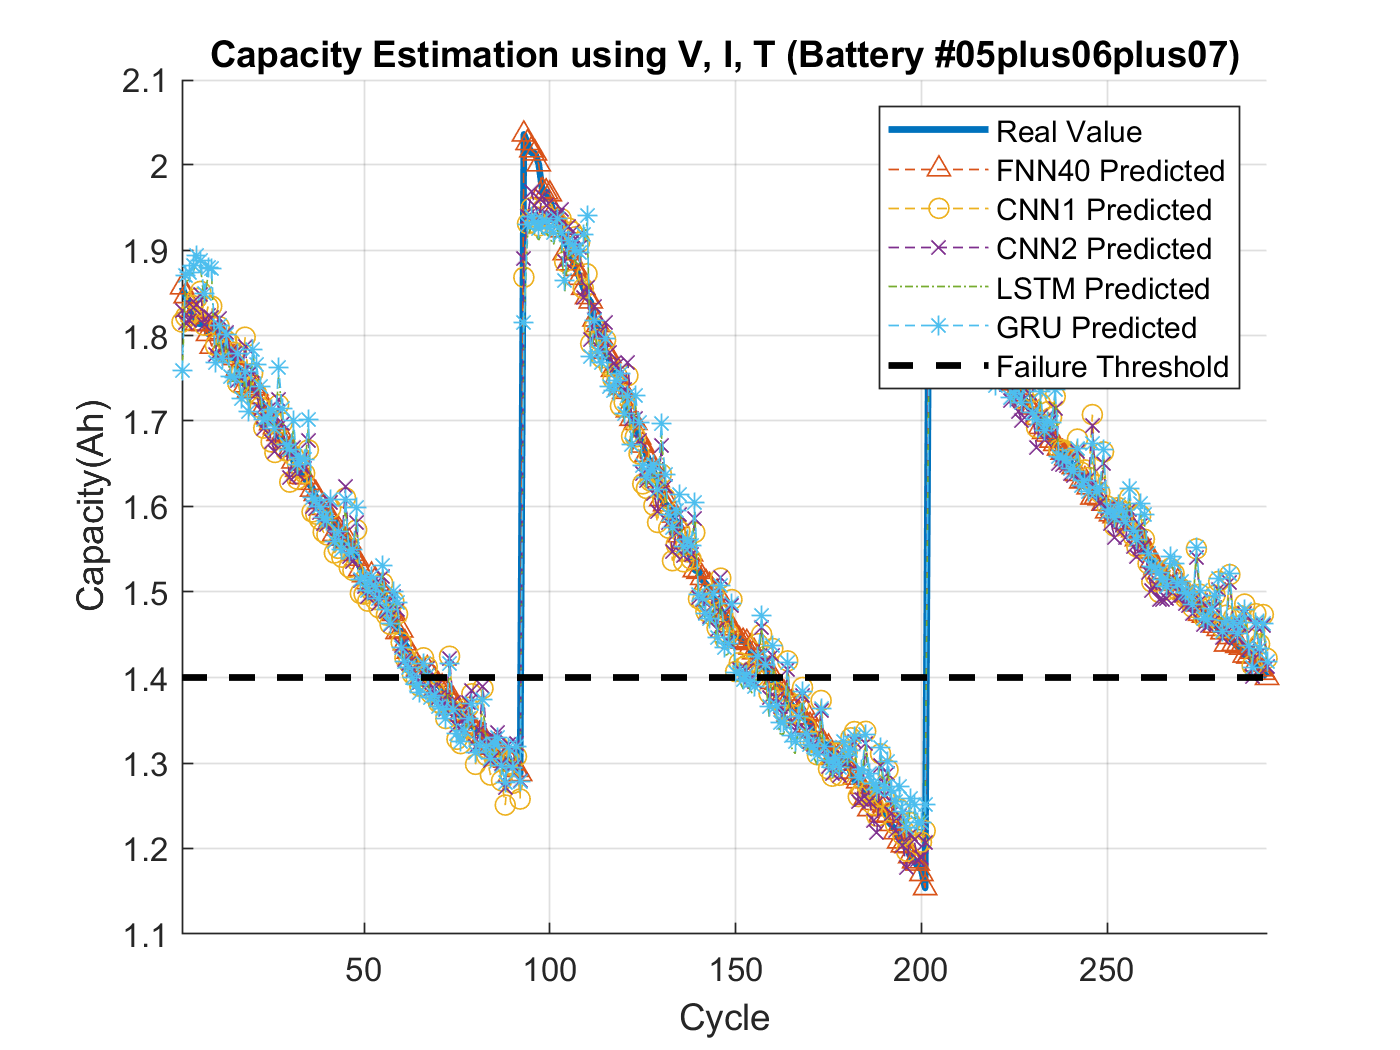


BatteryNumString = '05plus06plus07';
ModelNumString = '05plus06plus07' ;

pFNN40_05plus06plus07 = netFNN40_05plus06plus07_v2(x_05plus06plus07');
total_cycle = length(pFNN40_05plus06plus07);
cellx = num2cell(x_05plus06plus07', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_05plus06plus07 = predict(netCNN1_05plus06plus07_v2, x_4d);
pCNN2_05plus06plus07 = predict(netCNN2_05plus06plus07_v2, x_4d);
pLSTM_05plus06plus07 = cell2mat(predict(netLSTM_05plus06plus07_v2, num2cell(x_05plus06plus07', 1)));
pGRU_05plus06plus07 = cell2mat(predict(netGRU_05plus06plus07_v2, num2cell(x_05plus06plus07', 1)));

y_05plus06plus07 = yCap_05plus06plus07*cap_all_rate + cap_all_min;
pFNN40_05plus06plus07 = pFNN40_05plus06plus07*cap_all_rate + cap_all_min;
pCNN1_05plus06plus07 = pCNN1_05plus06plus07*cap_all_rate + cap_all_min;
pCNN2_05plus06plus07 = pCNN2_05plus06plus07*cap_all_rate + cap_all_min;
pLSTM_05plus06plus07 = pLSTM_05plus06plus07*cap_all_rate + cap_all_min;
pGRU_05plus06plus07 = pGRU_05plus06plus07*cap_all_rate + cap_all_min;

figure, hold on, grid on,
plot(y_05plus06plus07, 'linewidth', 2), plot(pFNN40_05plus06plus07, '^--'), plot(pCNN1_05plus06plus07, 'o--'), plot(pCNN2_05plus06plus07, 'x--'), plot(pLSTM_05plus06plus07, '-.'),plot(pGRU_05plus06plus07, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_05plus06plus07 = sqrt(mean(( y_05plus06plus07 - pFNN40_05plus06plus07' ).^2))

rmse_pFNN40_05plus06plus07 = 0.0041

rmse_pCNN1_05plus06plus07  = sqrt(mean(( y_05plus06plus07 - pCNN1_05plus06plus07 ).^2))

rmse_pCNN1_05plus06plus07 = single
0.0305

rmse_pCNN2_05plus06plus07  = sqrt(mean(( y_05plus06plus07 - pCNN2_05plus06plus07 ).^2))

rmse_pCNN2_05plus06plus07 = single
0.0274

rmse_pLSTM_05plus06plus07  = sqrt(mean(( y_05plus06plus07 - pLSTM_05plus06plus07 ).^2))

rmse_pLSTM_05plus06plus07 = single
0.0370

rmse_pGRU_05plus06plus07   = sqrt(mean(( y_05plus06plus07 - pGRU_05plus06plus07  ).^2))

rmse_pGRU_05plus06plus07 = single
0.0369


rmse_pFNN40_05plus06plus07

rmse_pFNN40_05plus06plus07 = 0.0041

rmse_pCNN1_05plus06plus07 

rmse_pCNN1_05plus06plus07 = single
0.0305

rmse_pCNN2_05plus06plus07 

rmse_pCNN2_05plus06plus07 = single
0.0274

rmse_pLSTM_05plus06plus07 

rmse_pLSTM_05plus06plus07 = single
0.0370

rmse_pGRU_05plus06plus07  

rmse_pGRU_05plus06plus07 = single
0.0369

# Prediciton #05plus06plus07pattern by model #05plus06plus07pattern - Full Data

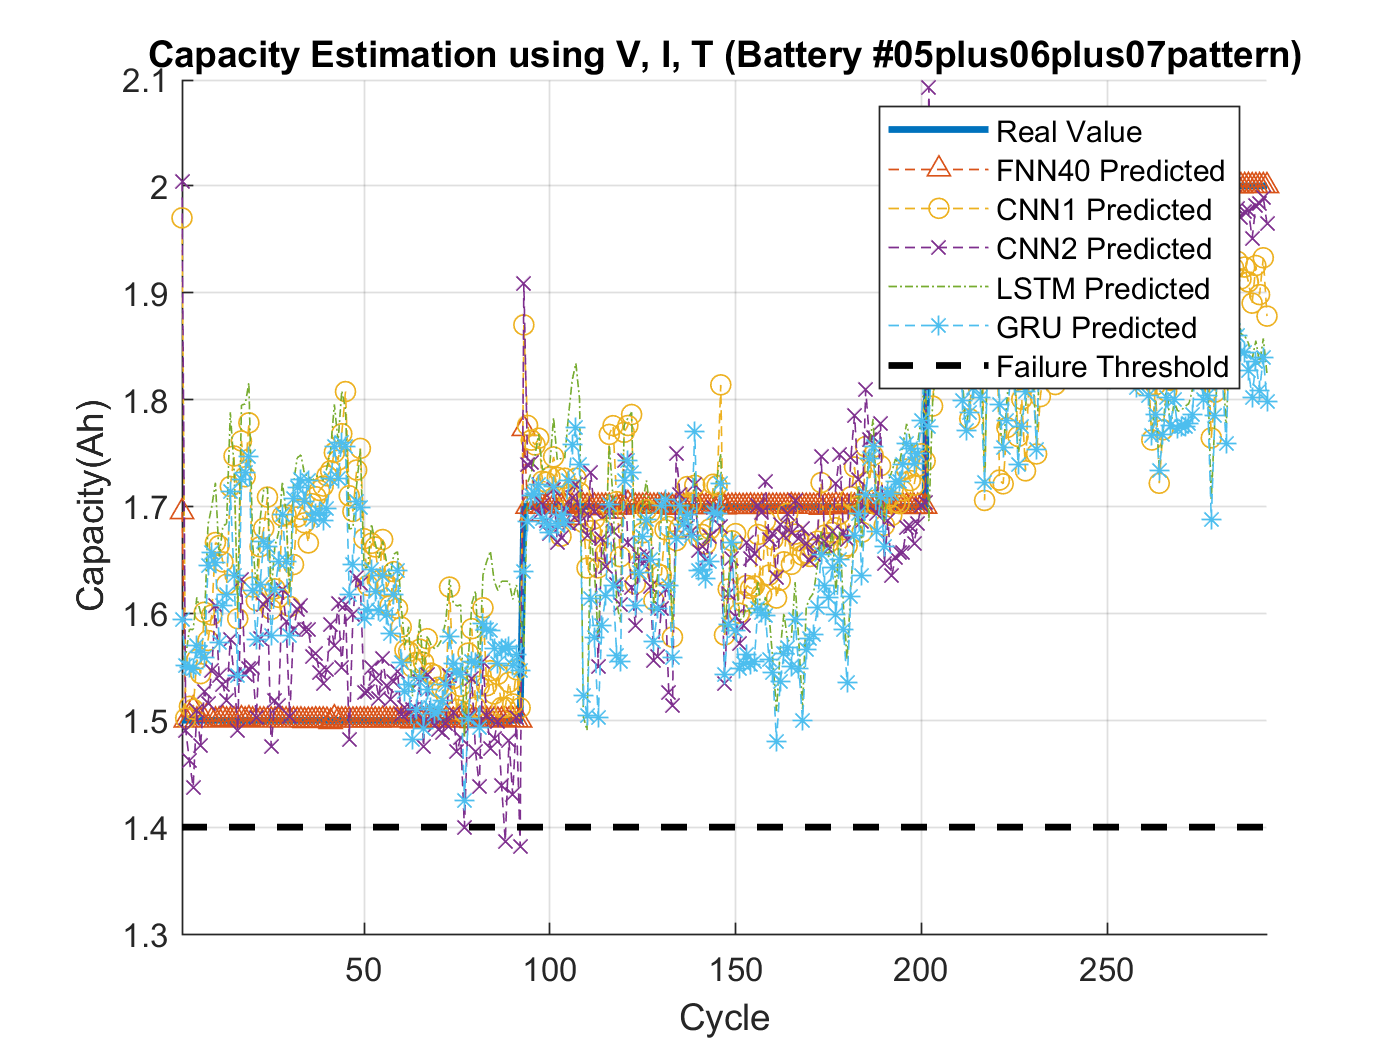


BatteryNumString = '05plus06plus07pattern';
ModelNumString = '05plus06plus07pattern' ;

pFNN40_05plus06plus07_pattern = netFNN40_05plus06plus07_pattern_v2(x_05plus06plus07_pattern');
total_cycle = length(pFNN40_05plus06plus07_pattern);
cellx = num2cell(x_05plus06plus07_pattern', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_05plus06plus07_pattern = predict(netCNN1_05plus06plus07_pattern_v2, x_4d);
pCNN2_05plus06plus07_pattern = predict(netCNN2_05plus06plus07_pattern_v2, x_4d);
pLSTM_05plus06plus07_pattern = cell2mat(predict(netLSTM_05plus06plus07_pattern_v2, num2cell(x_05plus06plus07_pattern', 1)));
pGRU_05plus06plus07_pattern = cell2mat(predict(netGRU_05plus06plus07_pattern_v2, num2cell(x_05plus06plus07_pattern', 1)));

y_05plus06plus07_pattern = yPattern_05plus06plus07*pattern_all_rate + pattern_all_min;
pFNN40_05plus06plus07_pattern = pFNN40_05plus06plus07_pattern*pattern_all_rate + pattern_all_min;
pCNN1_05plus06plus07_pattern = pCNN1_05plus06plus07_pattern*pattern_all_rate + pattern_all_min;
pCNN2_05plus06plus07_pattern = pCNN2_05plus06plus07_pattern*pattern_all_rate + pattern_all_min;
pLSTM_05plus06plus07_pattern = pLSTM_05plus06plus07_pattern*pattern_all_rate + pattern_all_min;
pGRU_05plus06plus07_pattern = pGRU_05plus06plus07_pattern*pattern_all_rate + pattern_all_min;

figure, hold on, grid on,
plot(y_05plus06plus07_pattern, 'linewidth', 2), plot(pFNN40_05plus06plus07_pattern, '^--'), plot(pCNN1_05plus06plus07_pattern, 'o--'), plot(pCNN2_05plus06plus07_pattern, 'x--'), plot(pLSTM_05plus06plus07_pattern, '-.'),plot(pGRU_05plus06plus07_pattern, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_05plus06plus07_pattern = sqrt(mean(( y_05plus06plus07_pattern - pFNN40_05plus06plus07_pattern' ).^2))

rmse_pFNN40_05plus06plus07_pattern = 0.0125

rmse_pCNN1_05plus06plus07_pattern  = sqrt(mean(( y_05plus06plus07_pattern - pCNN1_05plus06plus07_pattern ).^2))

rmse_pCNN1_05plus06plus07_pattern = single
0.1279

rmse_pCNN2_05plus06plus07_pattern  = sqrt(mean(( y_05plus06plus07_pattern - pCNN2_05plus06plus07_pattern ).^2))

rmse_pCNN2_05plus06plus07_pattern = single
0.0716

rmse_pLSTM_05plus06plus07_pattern  = sqrt(mean(( y_05plus06plus07_pattern - pLSTM_05plus06plus07_pattern ).^2))

rmse_pLSTM_05plus06plus07_pattern = single
0.1450

rmse_pGRU_05plus06plus07_pattern   = sqrt(mean(( y_05plus06plus07_pattern - pGRU_05plus06plus07_pattern  ).^2))

rmse_pGRU_05plus06plus07_pattern = single
0.1347


rmse_pFNN40_05plus06plus07_pattern

rmse_pFNN40_05plus06plus07_pattern = 0.0125

rmse_pCNN1_05plus06plus07_pattern 

rmse_pCNN1_05plus06plus07_pattern = single
0.1279

rmse_pCNN2_05plus06plus07_pattern 

rmse_pCNN2_05plus06plus07_pattern = single
0.0716

rmse_pLSTM_05plus06plus07_pattern 

rmse_pLSTM_05plus06plus07_pattern = single
0.1450

rmse_pGRU_05plus06plus07_pattern  

rmse_pGRU_05plus06plus07_pattern = single
0.1347

# Prediciton #05 by model #06 - Full Data

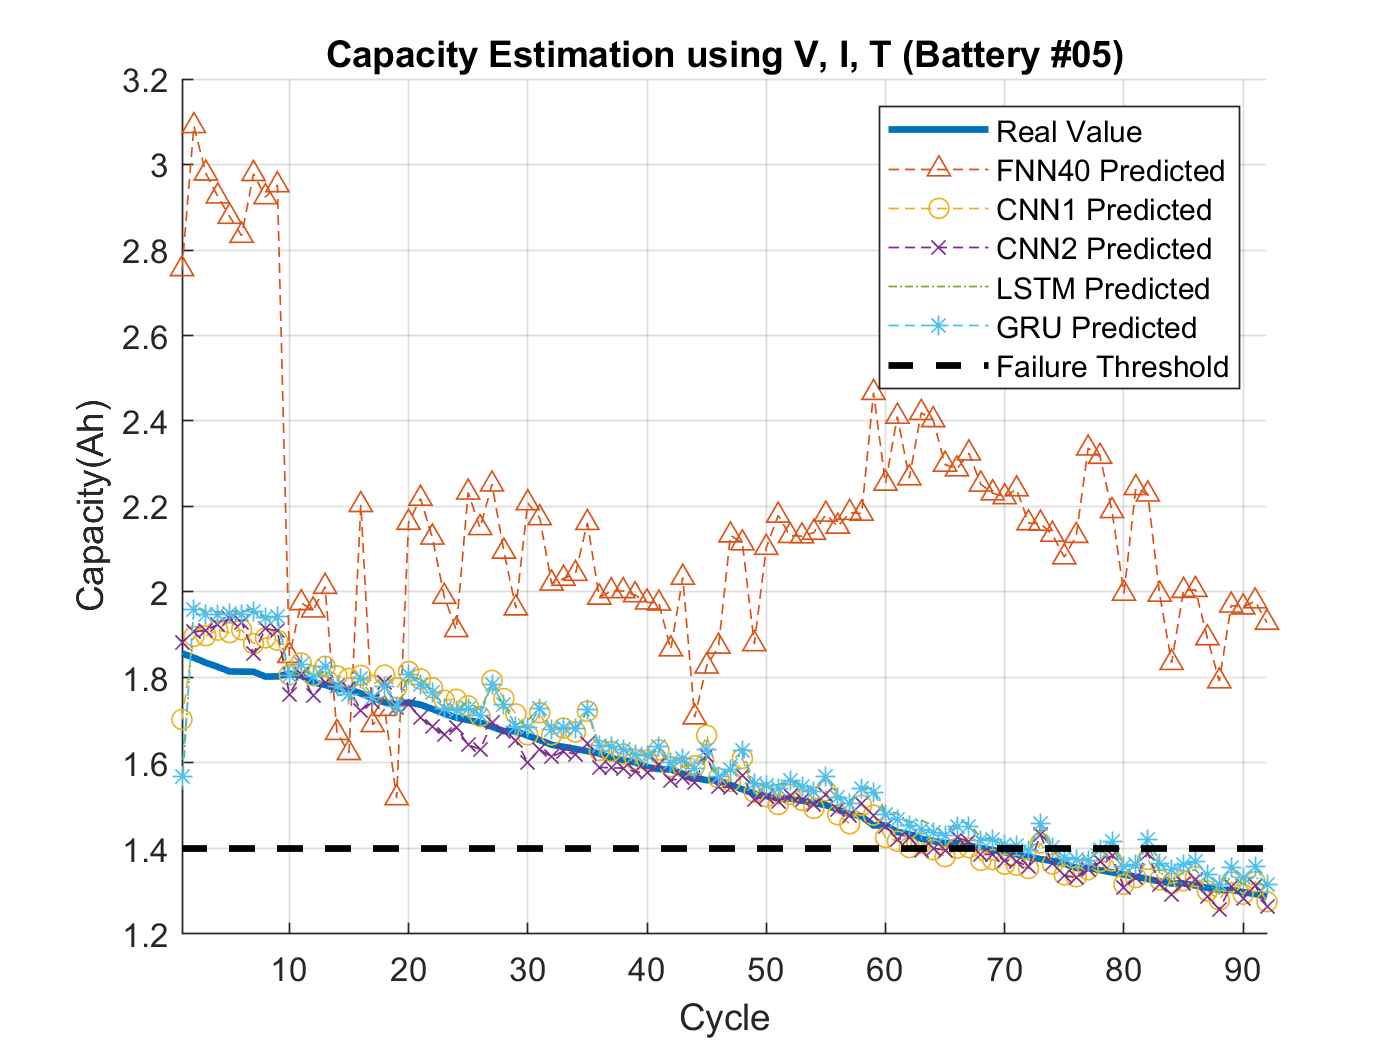


BatteryNumString = '05';
ModelNumString = '06' ;

pFNN40_05 = netFNN40_06_v2(x_05');
total_cycle = length(pFNN40_05);
cellx = num2cell(x_05', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_05 = predict(netCNN1_06_v2, x_4d);
pCNN2_05 = predict(netCNN2_06_v2, x_4d);
pLSTM_05 = cell2mat(predict(netLSTM_06_v2, num2cell(x_05', 1)));
pGRU_05 = cell2mat(predict(netGRU_06_v2, num2cell(x_05', 1)));

y_05 = yCap_05 *cap_all_rate + cap_all_min ;
pFNN40_05 = pFNN40_05 *cap_all_rate + cap_all_min ;
pCNN1_05 = pCNN1_05 *cap_all_rate + cap_all_min ;
pCNN2_05 = pCNN2_05 *cap_all_rate + cap_all_min ;
pLSTM_05 = pLSTM_05 *cap_all_rate + cap_all_min ;
pGRU_05 = pGRU_05 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_05, 'linewidth', 2), plot(pFNN40_05, '^--'), plot(pCNN1_05, 'o--'), plot(pCNN2_05, 'x--'), plot(pLSTM_05, '-.'),plot(pGRU_05, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_05 = sqrt(mean(( y_05(1:length(pFNN40_05'))' - pFNN40_05' ).^2))

rmse_pFNN40_05 =     0.4324    0.4395    0.4478    0.4550    0.4628    0.4631    0.4633    0.4718    0.4714    0.4664    0.4699    0.4821    0.4864    0.4940    0.4940    0.5024    0.5108    0.5186    0.5233    0.5187    0.5230    0.5312    0.5397    0.5478    0.5525    0.5572    0.5653    0.5740    0.5739    0.5831    0.5914    0.6010    0.6051    0.6095    0.6138    0.6187    0.6280    0.6322    0.6366    0.6463    0.6503    0.6511    0.6601    0.6688    0.6733    0.6736    0.6830    0.6925    0.7017    0.7065


rmse_pCNN1_05  = sqrt(mean(( y_05 - pCNN1_05 ).^2))

rmse_pCNN1_05 = single
0.0442

rmse_pCNN2_05  = sqrt(mean(( y_05 - pCNN2_05 ).^2))

rmse_pCNN2_05 = single
0.0376

rmse_pLSTM_05  = sqrt(mean(( y_05 - pLSTM_05 ).^2))

rmse_pLSTM_05 = single
0.0647

rmse_pGRU_05   = sqrt(mean(( y_05 - pGRU_05  ).^2))

rmse_pGRU_05 = single
0.0629


rmse_pFNN40_05

rmse_pFNN40_05 =     0.4324    0.4395    0.4478    0.4550    0.4628    0.4631    0.4633    0.4718    0.4714    0.4664    0.4699    0.4821    0.4864    0.4940    0.4940    0.5024    0.5108    0.5186    0.5233    0.5187    0.5230    0.5312    0.5397    0.5478    0.5525    0.5572    0.5653    0.5740    0.5739    0.5831    0.5914    0.6010    0.6051    0.6095    0.6138    0.6187    0.6280    0.6322    0.6366    0.6463    0.6503    0.6511    0.6601    0.6688    0.6733    0.6736    0.6830    0.6925    0.7017    0.7065


rmse_pCNN1_05

rmse_pCNN1_05 = single
0.0442

rmse_pCNN2_05

rmse_pCNN2_05 = single
0.0376

rmse_pLSTM_05

rmse_pLSTM_05 = single
0.0647

rmse_pGRU_05

rmse_pGRU_05 = single
0.0629

# Prediciton #0506 by model #05 - Full Data


BatteryNumString = '0506';
ModelNumString = '05' ;

pFNN40_0506 = netFNN40_05_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')
rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))

rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506 by model #05 - From Pattern Change 

FNN데이타가 이상하다. 다시 점검 필요

BatteryNumString = '0506';
ModelNumString = '05' ;

pFNN40_0506 = netFNN40_05_v2(x_0506_change');   
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506_change', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05_v2, num2cell(x_0506_change', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05_v2, num2cell(x_0506_change', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
y_0506_change = y_0506(idx_0506_change:end);
pFNN40_0506_change = pFNN40_0506 *cap_all_rate + cap_all_min ; pFNN40_0506 = [yCap_0506_change_before pFNN40_0506_change];
pCNN1_0506_change = pCNN1_0506 *cap_all_rate + cap_all_min ;   pCNN1_0506 = [yCap_0506_change_before' ; pCNN1_0506_change];
pCNN2_0506_change = pCNN2_0506 *cap_all_rate + cap_all_min ;   pCNN2_0506 = [yCap_0506_change_before' ; pCNN2_0506_change];
pLSTM_0506_change = pLSTM_0506 *cap_all_rate + cap_all_min ;   pLSTM_0506 = [yCap_0506_change_before' ; pLSTM_0506_change];
pGRU_0506_change = pGRU_0506 *cap_all_rate + cap_all_min ;     pGRU_0506 = [yCap_0506_change_before' ; pGRU_0506_change];

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506_change(1:length(pFNN40_0506_change'))' - pFNN40_0506_change' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506_change - pCNN1_0506_change ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506_change - pCNN2_0506_change ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506_change - pLSTM_0506_change ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506_change - pGRU_0506_change  ).^2))

rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506 by model #06 - Full Data


BatteryNumString = '0506';
ModelNumString = '06' ;


pFNN40_0506 = netFNN40_06_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_06_v2, x_4d);
pCNN2_0506 = predict(netCNN2_06_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_06_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_06_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')
rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506 by model #06 - From Pattern Change 


BatteryNumString = '0506';
ModelNumString = '06' ;

pFNN40_0506 = netFNN40_06_v2(x_0506_change');   
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506_change', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_06_v2, x_4d);
pCNN2_0506 = predict(netCNN2_06_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_06_v2, num2cell(x_0506_change', 1)));
pGRU_0506 = cell2mat(predict(netGRU_06_v2, num2cell(x_0506_change', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
y_0506_change = y_0506(idx_0506_change:end);
pFNN40_0506_change = pFNN40_0506 *cap_all_rate + cap_all_min ; pFNN40_0506 = [yCap_0506_change_before pFNN40_0506_change];
pCNN1_0506_change = pCNN1_0506 *cap_all_rate + cap_all_min ;   pCNN1_0506 = [yCap_0506_change_before' ; pCNN1_0506_change];
pCNN2_0506_change = pCNN2_0506 *cap_all_rate + cap_all_min ;   pCNN2_0506 = [yCap_0506_change_before' ; pCNN2_0506_change];
pLSTM_0506_change = pLSTM_0506 *cap_all_rate + cap_all_min ;   pLSTM_0506 = [yCap_0506_change_before' ; pLSTM_0506_change];
pGRU_0506_change = pGRU_0506 *cap_all_rate + cap_all_min ;     pGRU_0506 = [yCap_0506_change_before' ; pGRU_0506_change];

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506_change(1:length(pFNN40_0506_change'))' - pFNN40_0506_change' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506_change - pCNN1_0506_change ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506_change - pCNN2_0506_change ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506_change - pLSTM_0506_change ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506_change - pGRU_0506_change  ).^2))

rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506 by model #07 - Full Data


BatteryNumString = '0506';
ModelNumString = '07' ;


pFNN40_0506 = netFNN40_07_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_07_v2, x_4d);
pCNN2_0506 = predict(netCNN2_07_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_07_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_07_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')
rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506 by model #07 - From Pattern Change 


BatteryNumString = '0506';
ModelNumString = '07' ;

pFNN40_0506 = netFNN40_07_v2(x_0506_change');   
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506_change', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_07_v2, x_4d);
pCNN2_0506 = predict(netCNN2_07_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_07_v2, num2cell(x_0506_change', 1)));
pGRU_0506 = cell2mat(predict(netGRU_07_v2, num2cell(x_0506_change', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
y_0506_change = y_0506(idx_0506_change:end);
pFNN40_0506_change = pFNN40_0506 *cap_all_rate + cap_all_min ; pFNN40_0506 = [yCap_0506_change_before pFNN40_0506_change];
pCNN1_0506_change = pCNN1_0506 *cap_all_rate + cap_all_min ;   pCNN1_0506 = [yCap_0506_change_before' ; pCNN1_0506_change];
pCNN2_0506_change = pCNN2_0506 *cap_all_rate + cap_all_min ;   pCNN2_0506 = [yCap_0506_change_before' ; pCNN2_0506_change];
pLSTM_0506_change = pLSTM_0506 *cap_all_rate + cap_all_min ;   pLSTM_0506 = [yCap_0506_change_before' ; pLSTM_0506_change];
pGRU_0506_change = pGRU_0506 *cap_all_rate + cap_all_min ;     pGRU_0506 = [yCap_0506_change_before' ; pGRU_0506_change];

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506_change(1:length(pFNN40_0506_change'))' - pFNN40_0506_change' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506_change - pCNN1_0506_change ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506_change - pCNN2_0506_change ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506_change - pLSTM_0506_change ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506_change - pGRU_0506_change  ).^2))

rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506 by model #05plus06 - Full Data


BatteryNumString = '0506';
ModelNumString = '05plus06'

pFNN40_0506 = netFNN40_05plus06_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506 by model #05plus06plus07 - Full Data


BatteryNumString = '0506';
ModelNumString = '05plus06plus07'

pFNN40_0506 = netFNN40_05plus06plus07_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06plus07_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06plus07_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06plus07_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06plus07_v2, num2cell(x_0506', 1)));

y_0506 = yCap_0506 *cap_all_rate + cap_all_min ;
pFNN40_0506 = pFNN40_0506 *cap_all_rate + cap_all_min ;
pCNN1_0506 = pCNN1_0506 *cap_all_rate + cap_all_min ;
pCNN2_0506 = pCNN2_0506 *cap_all_rate + cap_all_min ;
pLSTM_0506 = pLSTM_0506 *cap_all_rate + cap_all_min ;
pGRU_0506 = pGRU_0506 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

# Prediciton #0506pattern by model #05plus06plus07pattern - Full Data = FNN 이 잘 예측함


BatteryNumString = '0506pattern';
ModelNumString = '05plus06plus07pattern'

pFNN40_0506 = netFNN40_05plus06plus07_pattern_v2(x_0506');
total_cycle = length(pFNN40_0506);
cellx = num2cell(x_0506', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0506 = predict(netCNN1_05plus06plus07_pattern_v2, x_4d);
pCNN2_0506 = predict(netCNN2_05plus06plus07_pattern_v2, x_4d);
pLSTM_0506 = cell2mat(predict(netLSTM_05plus06plus07_pattern_v2, num2cell(x_0506', 1)));
pGRU_0506 = cell2mat(predict(netGRU_05plus06plus07_pattern_v2, num2cell(x_0506', 1)));

y_0506 = yPattern_0506 *pattern_all_rate + pattern_all_min ;
pFNN40_0506 = pFNN40_0506 *pattern_all_rate + pattern_all_min ;
pCNN1_0506 = pCNN1_0506 *pattern_all_rate + pattern_all_min ;
pCNN2_0506 = pCNN2_0506 *pattern_all_rate + pattern_all_min ;
pLSTM_0506 = pLSTM_0506 *pattern_all_rate + pattern_all_min ;
pGRU_0506 = pGRU_0506 *pattern_all_rate + pattern_all_min ;

figure, hold on, grid on,
plot(y_0506, 'linewidth', 2), plot(pFNN40_0506, '^--'), plot(pCNN1_0506, 'o--'), plot(pCNN2_0506, 'x--'), plot(pLSTM_0506, '-.'),plot(pGRU_0506, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0506 = sqrt(mean(( y_0506(1:length(pFNN40_0506'))' - pFNN40_0506' ).^2))
rmse_pCNN1_0506  = sqrt(mean(( y_0506 - pCNN1_0506 ).^2))
rmse_pCNN2_0506  = sqrt(mean(( y_0506 - pCNN2_0506 ).^2))
rmse_pLSTM_0506  = sqrt(mean(( y_0506 - pLSTM_0506 ).^2))
rmse_pGRU_0506   = sqrt(mean(( y_0506 - pGRU_0506  ).^2))
rmse_pFNN40_0506
rmse_pCNN1_0506
rmse_pCNN2_0506
rmse_pLSTM_0506
rmse_pGRU_0506

%%%%%%%%%%%%%%%%%%%%%%%

# Prediciton #0605 by model #05 - Full Data


BatteryNumString = '0605';
ModelNumString = '05';
pFNN40_0605 = netFNN40_05_v2(x_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(x_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_05_v2, x_4d);
pCNN2_0605 = predict(netCNN2_05_v2, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_05_v2, num2cell(x_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_05_v2, num2cell(x_0605', 1)));

y_0605 = yCap_0605 *cap_all_rate + cap_all_min ;
pFNN40_0605 = pFNN40_0605 *cap_all_rate + cap_all_min ;
pCNN1_0605 = pCNN1_0605 *cap_all_rate + cap_all_min ;
pCNN2_0605 = pCNN2_0605 *cap_all_rate + cap_all_min ;
pLSTM_0605 = pLSTM_0605 *cap_all_rate + cap_all_min ;
pGRU_0605 = pGRU_0605 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605')) - pFNN40_0605' ).^2))
rmse_pCNN1_0605  = sqrt(mean(( y_0605 - pCNN1_0605 ).^2))
rmse_pCNN2_0605  = sqrt(mean(( y_0605 - pCNN2_0605 ).^2))
rmse_pLSTM_0605  = sqrt(mean(( y_0605 - pLSTM_0605 ).^2))
rmse_pGRU_0605   = sqrt(mean(( y_0605 - pGRU_0605  ).^2))
rmse_pFNN40_0605
rmse_pCNN1_0605
rmse_pCNN2_0605
rmse_pLSTM_0605
rmse_pGRU_0605

# Prediciton #0605 by model #06 - Full Data


BatteryNumString = '0605';
ModelNumString = '06';

pFNN40_0605 = netFNN40_06_v2(x_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(x_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_06_v2, x_4d);
pCNN2_0605 = predict(netCNN2_06_v2, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_06_v2, num2cell(x_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_06_v2, num2cell(x_0605', 1)));

y_0605 = yCap_0605 *cap_all_rate + cap_all_min ;
pFNN40_0605 = pFNN40_0605 *cap_all_rate + cap_all_min ;
pCNN1_0605 = pCNN1_0605 *cap_all_rate + cap_all_min ;
pCNN2_0605 = pCNN2_0605 *cap_all_rate + cap_all_min ;
pLSTM_0605 = pLSTM_0605 *cap_all_rate + cap_all_min ;
pGRU_0605 = pGRU_0605 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605')) - pFNN40_0605' ).^2))
rmse_pCNN1_0605  = sqrt(mean(( y_0605 - pCNN1_0605 ).^2))
rmse_pCNN2_0605  = sqrt(mean(( y_0605 - pCNN2_0605 ).^2))
rmse_pLSTM_0605  = sqrt(mean(( y_0605 - pLSTM_0605 ).^2))
rmse_pGRU_0605   = sqrt(mean(( y_0605 - pGRU_0605  ).^2))
rmse_pFNN40_0605
rmse_pCNN1_0605
rmse_pCNN2_0605
rmse_pLSTM_0605
rmse_pGRU_0605

# Prediciton #0605 by model #07 - Full Data


BatteryNumString = '0605';
ModelNumString = '07';
pFNN40_0605 = netFNN40_07_v2(x_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(x_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_07_v2, x_4d);
pCNN2_0605 = predict(netCNN2_07_v2, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_07_v2, num2cell(x_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_07_v2, num2cell(x_0605', 1)));

y_0605 = yCap_0605 *cap_all_rate + cap_all_min ;
pFNN40_0605 = pFNN40_0605 *cap_all_rate + cap_all_min ;
pCNN1_0605 = pCNN1_0605 *cap_all_rate + cap_all_min ;
pCNN2_0605 = pCNN2_0605 *cap_all_rate + cap_all_min ;
pLSTM_0605 = pLSTM_0605 *cap_all_rate + cap_all_min ;
pGRU_0605 = pGRU_0605 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605')) - pFNN40_0605' ).^2))
rmse_pCNN1_0605  = sqrt(mean(( y_0605 - pCNN1_0605 ).^2))
rmse_pCNN2_0605  = sqrt(mean(( y_0605 - pCNN2_0605 ).^2))
rmse_pLSTM_0605  = sqrt(mean(( y_0605 - pLSTM_0605 ).^2))
rmse_pGRU_0605   = sqrt(mean(( y_0605 - pGRU_0605  ).^2))
rmse_pFNN40_0605
rmse_pCNN1_0605
rmse_pCNN2_0605
rmse_pLSTM_0605
rmse_pGRU_0605

# Prediciton #0605 by model #05plus06 - Full Data


BatteryNumString = '0605';
ModelNumString = '05plus06';
pFNN40_0605 = netFNN40_05plus06_v2(x_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(x_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_05plus06_v2, x_4d);
pCNN2_0605 = predict(netCNN2_05plus06_v2, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_05plus06_v2, num2cell(x_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_05plus06_v2, num2cell(x_0605', 1)));

y_0605 = yCap_0605 *cap_all_rate + cap_all_min ;
pFNN40_0605 = pFNN40_0605 *cap_all_rate + cap_all_min ;
pCNN1_0605 = pCNN1_0605 *cap_all_rate + cap_all_min ;
pCNN2_0605 = pCNN2_0605 *cap_all_rate + cap_all_min ;
pLSTM_0605 = pLSTM_0605 *cap_all_rate + cap_all_min ;
pGRU_0605 = pGRU_0605 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605')) - pFNN40_0605' ).^2))
rmse_pCNN1_0605  = sqrt(mean(( y_0605 - pCNN1_0605 ).^2))
rmse_pCNN2_0605  = sqrt(mean(( y_0605 - pCNN2_0605 ).^2))
rmse_pLSTM_0605  = sqrt(mean(( y_0605 - pLSTM_0605 ).^2))
rmse_pGRU_0605   = sqrt(mean(( y_0605 - pGRU_0605  ).^2))
rmse_pFNN40_0605
rmse_pCNN1_0605
rmse_pCNN2_0605
rmse_pLSTM_0605
rmse_pGRU_0605

# Prediciton #0605 by model #05plus06plus07 - Full Data


BatteryNumString = '0605';
ModelNumString = '05plus06';
pFNN40_0605 = netFNN40_05plus06plus07_v2(x_0605');
total_cycle = length(pFNN40_0605);
cellx = num2cell(x_0605', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, charVIT_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN1_0605 = predict(netCNN1_05plus06plus07_v2, x_4d);
pCNN2_0605 = predict(netCNN2_05plus06plus07_v2, x_4d);
pLSTM_0605 = cell2mat(predict(netLSTM_05plus06plus07_v2, num2cell(x_0605', 1)));
pGRU_0605 = cell2mat(predict(netGRU_05plus06plus07_v2, num2cell(x_0605', 1)));

y_0605 = yCap_0605 *cap_all_rate + cap_all_min ;
pFNN40_0605 = pFNN40_0605 *cap_all_rate + cap_all_min ;
pCNN1_0605 = pCNN1_0605 *cap_all_rate + cap_all_min ;
pCNN2_0605 = pCNN2_0605 *cap_all_rate + cap_all_min ;
pLSTM_0605 = pLSTM_0605 *cap_all_rate + cap_all_min ;
pGRU_0605 = pGRU_0605 *cap_all_rate + cap_all_min ;

figure, hold on, grid on,
plot(y_0605, 'linewidth', 2), plot(pFNN40_0605, '^--'), plot(pCNN1_0605, 'o--'), plot(pCNN2_0605, 'x--'), plot(pLSTM_0605, '-.'),plot(pGRU_0605, '*--'),
plot(1:total_cycle, 1.4*ones(1, total_cycle),'k--','LineWidth', 2), xlim([1 total_cycle])
title(['Capacity Estimation using V, I, T (Battery #', BatteryNumString, ')'])
xlabel Cycle, ylabel Capacity(Ah)
legend('Real Value', 'FNN40 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted','GRU Predicted', 'Failure Threshold')

rmse_pFNN40_0605 = sqrt(mean(( y_0605(1:length(pFNN40_0605')) - pFNN40_0605' ).^2))
rmse_pCNN1_0605  = sqrt(mean(( y_0605 - pCNN1_0605 ).^2))
rmse_pCNN2_0605  = sqrt(mean(( y_0605 - pCNN2_0605 ).^2))
rmse_pLSTM_0605  = sqrt(mean(( y_0605 - pLSTM_0605 ).^2))
rmse_pGRU_0605   = sqrt(mean(( y_0605 - pGRU_0605  ).^2))
rmse_pFNN40_0605
rmse_pCNN1_0605
rmse_pCNN2_0605
rmse_pLSTM_0605
rmse_pGRU_0605